clc
clear
close all

E-Glass Material Properties

E_11 = 45e9 % Axial Elastic Modulus (Pa)

E_11 = 4.5000e+10

E_22 = 12e9 % Transverse Elastic Modulus (Pa)

E_22 = 1.2000e+10

G_12 = 5.5e9 % Shear Modulus (Pa)

G_12 = 5.5000e+09

nu_12 = 0.28 % Poisson's Ratio

nu_12 = 0.2800

Loading Specifications

sigma_xx = 1762e6 % Normal stress in x (Pa)

sigma_xx = 1.7620e+09

sigma_yy = 986e6 % Normal stress in x (Pa)

sigma_yy = 986000000

tau_xy = 782e6 % Normal stress in x (Pa)

tau_xy = 782000000

theta = deg2rad(54) % Material orientation (rad)

theta = 0.9425

Compliance Matrix

S1 = [1/E_11 -nu_12/E_11 0; % 1/Pa
    -nu_12/E_11 1/E_22 0;
    0 0 1/G_12]

S1 = 1.0e-09 *

    0.0222   -0.0062         0
   -0.0062    0.0833         0
         0         0    0.1818


Simplification

m = cos(theta) % x component

m = 0.5878

n = sin(theta) % y component

n = 0.8090

Stress Transformation Matrix

function T1 = stressTransform(m,n)
T1 = [m^2 n^2 2*m*n;
    n^2 m^2 -2*m*n;
    -m*n m*n m^2-n^2];
end

Strain Transformation Matrix

function T2 = strainTransform(m,n)
T2 = [m^2 n^2 m*n;
    n^2 m^2 -m*n;
    -2*m*n 2*m*n m^2-n^2];
end

Stress Computations

trans_stress = stressTransform(m,n)*[sigma_xx; sigma_yy; tau_xy]; % Transformed stress
sigma_11 = trans_stress(1)

sigma_11 = 1.9978e+09

sigma_22 = trans_stress(2)

sigma_22 = 7.5017e+08

tau_12 = trans_stress(3)

tau_12 = -6.1066e+08

Strain Computations

trans_strain = S1*trans_stress; % Transformed strain (dimensionless)
epsilon_11 = trans_strain(1)

epsilon_11 = 0.0397

epsilon_22 = trans_strain(2)

epsilon_22 = 0.0501

gamma_12 = trans_strain(3)

gamma_12 = -0.1110


cart_strain = strainTransform(m,n) \ trans_strain; % Strain in cartesian coordinates (dimensionless)
epsilon_xx = cart_strain(1)

epsilon_xx = 0.0993

epsilon_yy = cart_strain(2)

epsilon_yy = -0.0095

gamma_xy = cart_strain(3)

gamma_xy = 0.0245

Variable Initialization

theta_n = linspace(0,pi/2,100) % 100 angles from 0 to 90 degrees

theta_n =          0    0.0159    0.0317    0.0476    0.0635    0.0793    0.0952    0.1111    0.1269    0.1428    0.1587    0.1745    0.1904    0.2063    0.2221    0.2380    0.2539    0.2697    0.2856    0.3015    0.3173    0.3332    0.3491    0.3649    0.3808    0.3967    0.4125    0.4284    0.4443    0.4601    0.4760    0.4919    0.5077    0.5236    0.5395    0.5553    0.5712    0.5871    0.6029    0.6188    0.6347    0.6505    0.6664    0.6823    0.6981    0.7140    0.7299    0.7457    0.7616    0.7775



sigma_11_n = zeros(1,100);
sigma_22_n = zeros(1,100);
tau_12_n = zeros(1,100);

epsilon_11_n = zeros(1,100);
epsilon_22_n = zeros(1,100);
gamma_12_n = zeros(1,100);

epsilon_xx_n = zeros(1,100);
epsilon_yy_n = zeros(1,100);
gamma_xy_n = zeros(1,100);

Calculate stress and strain values for 0 < theta < 90 deg

for i=1:100
q = cos(theta_n(i));
r = sin(theta_n(i));

T1_n = stressTransform(q,r); % Stress transformation matrix for theta_n
T2_n = strainTransform(q,r); % Strain transformation matrix for theta_n
S_n = (T2_n\S1)*T1_n; % Compliance matrix for theta_n

trans_stress_n = T1_n*[sigma_xx; sigma_yy; tau_xy];
sigma_11_n(i) = trans_stress_n(1);
sigma_22_n(i) = trans_stress_n(2);
tau_12_n(i) = trans_stress_n(3);

trans_strain_n = S_n*trans_stress_n;
epsilon_11_n(i) = trans_strain_n(1);
epsilon_22_n(i) = trans_strain_n(2);
gamma_12_n(i) = trans_strain_n(3);
if i==3
    disp(T2_n)
end

cart_strain_n = T2_n\trans_strain_n;
epsilon_xx_n(i) = cart_strain_n(1);
epsilon_yy_n(i) = cart_strain_n(2);
gamma_xy_n(i) = cart_strain_n(3);
end

    0.9990    0.0010    0.0317
    0.0010    0.9990   -0.0317
   -0.0634    0.0634    0.9980


Calculate Minmum and Maximum Values

epsilon_11_max = max(epsilon_11_n)

epsilon_11_max = 0.1510

epsilon_11_min = min(epsilon_11_n)

epsilon_11_min = 0.0306

epsilon_22_max = max(epsilon_22_n)

epsilon_22_max = 0.0712

epsilon_22_min = min(epsilon_22_n)

epsilon_22_min = -0.0046

gamma_12_max = max(gamma_12_n)

gamma_12_max = 0.1422

gamma_12_min = min(gamma_12_n)

gamma_12_min = -0.1851

Plot Stress in Material Orientation

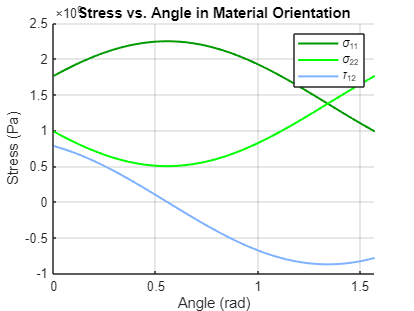

figure('Name','Stress in Mat Ori');
hold on;
plot(theta_n, sigma_11_n, 'Color', [0 0.6 0], 'LineWidth', 1.5);
plot(theta_n, sigma_22_n, 'Color', [0 1 0], 'LineWidth', 1.5);
plot(theta_n, tau_12_n, 'Color', [0.5, 0.7, 1], 'LineWidth', 1.5);
hold off;
xlabel('Angle (rad)');
ylabel('Stress (Pa)');
legend('\sigma_{11}', '\sigma_{22}', '\tau_{12}');
title('Stress vs. Angle in Material Orientation');
grid on;

Plot Strain in Material Orientation

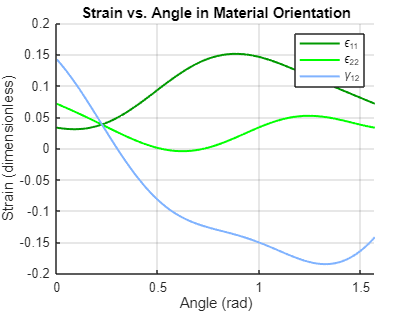

figure('Name','Strain in Mat Ori');
hold on;
plot(theta_n, epsilon_11_n, 'Color', [0 0.6 0], 'LineWidth', 1.5);
plot(theta_n, epsilon_22_n, 'Color', [0 1 0], 'LineWidth', 1.5);
plot(theta_n, gamma_12_n, 'Color', [0.5, 0.7, 1], 'LineWidth', 1.5);
hold off;
xlabel('Angle (rad)');
ylabel('Strain (dimensionless)');
legend('\epsilon_{11}', '\epsilon_{22}', '\gamma_{12}');
title('Strain vs. Angle in Material Orientation');
grid on;

Plot Strain in Cartesian Coordinates

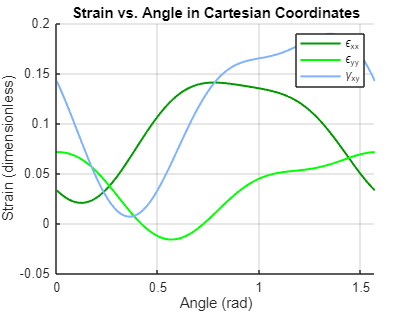

figure('Name','Strain in Cart Coor');
hold on;
plot(theta_n, epsilon_xx_n, 'Color', [0 0.6 0], 'LineWidth', 1.5);
plot(theta_n, epsilon_yy_n, 'Color', [0 1 0], 'LineWidth', 1.5);
plot(theta_n, gamma_xy_n, 'Color', [0.5, 0.7, 1], 'LineWidth', 1.5);
hold off;
xlabel('Angle (rad)');
ylabel('Strain (dimensionless)');
legend('\epsilon_{xx}', '\epsilon_{yy}', '\gamma_{xy}');
title('Strain vs. Angle in Cartesian Coordinates');
grid on;